## -----------------------------Read Data----------------------------

[x_i,x_q,y_i,y_q,dim]=ReadFile_Validation('A');
% 转换为复信号，i表示实部，q表示虚部
x_sync = x_i + 1i * x_q; % PA_input复数形式
y_sync = y_i + 1i * y_q; % PA_output复数形式

## -----------------------------Model I----------------------------


% 设置输入/输出矩阵
M=2; % 记忆深度
X1 = zeros(2*(M + 1), dim-M); 
for j = 1:length(y_i) - M
    X1(:, j) = [y_i(j : j + M); y_q(j : j + M)];
end 
Y = [x_i(M + 1 : end)'; x_q(M + 1 : end)']; 
% 调整参数和训练模型
net = feedforwardnet(5);% 神经元数量 
trained_net = train(net, X1, Y);
% 查看单级DPD的模型性能
Y_pred = sim(trained_net, X1); 
a = Y_pred(1, :) + Y_pred(2, :) * 1i; % PA输出预测值
b = Y(1, :) + Y(2, :) * 1i; % PA输出值（）
nmse_DPD = NMSE_dB(a, b);
fprintf('DPD的NMSE为 %f dB', nmse_DPD);

DPD的NMSE为 -27.623671 dB


save('Algorithm_A/NN.mat', 'trained_net');

## -----------------------------Model II----------------------------

load('Algorithm_A/Model.mat');
%  Set Input/Output Matrix  
M=2; % Memory Depth
X = zeros(2*(M + 1), dim-M);
for j = 1:length(y_i) - M
    X(:, j) = [y_i(j : j + M); y_q(j : j + M)];
end
X = X.';
Y_i = x_i(M + 1 : end);
Y_q = x_q(M + 1 : end);
XY = [X, Y_i, Y_q];
%  Train Models in App and Export to Workspace

%  Check Modeling Performance and Save Models
y_model = Model_I.predictFcn(X) + Model_Q.predictFcn(X) * 1i;
y_measure = Y_i + Y_q * 1i;
nmse_DPD = NMSE_dB(y_model, y_measure);
fprintf('DPD的NMSE为 %f dB', nmse_DPD);

DPD的NMSE为 -18.751428 dB


save('Algorithm_A\Model.mat', 'Model_I', 'Model_Q');

## -----------------------------Model III----------------------------

｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０３　｜　　　　　　　０．７２　｜　　　　　　０．６６　｜　　０．２５８７　｜　０．２１９４　｜　　０．００５０　｜
｜　５００　｜　　５００　｜　　　　　００：００：１３　｜　　　　　　　０．０２　｜　　　　　　０．０２　｜　　０．０００３　｜　０．０００３　｜　　０．００５０　｜
｜　１０００　｜　１０００　｜　　　　　００：００：２１　｜　　　　　　　０．０２　｜　　　　　　０．０２　｜　　０．０００２　｜　０．０００２　｜　　０．００２５　｜
｜　１５００　｜　１５００　｜　　　　　００：００：２９　｜　　　　　　　０．０２　｜　　　　　　０．０２　｜　　０．０００２　｜　０．０００２　｜　　０．００１２　｜
｜　２０００　｜　２０００　｜　　　　　００：００：３８　｜　　　　　　　０．０２　｜　　　　　　０．０２　｜　　０．０００２　｜　０．０００２　｜　　０．０００６　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
训练结束: 已完成最大轮数。


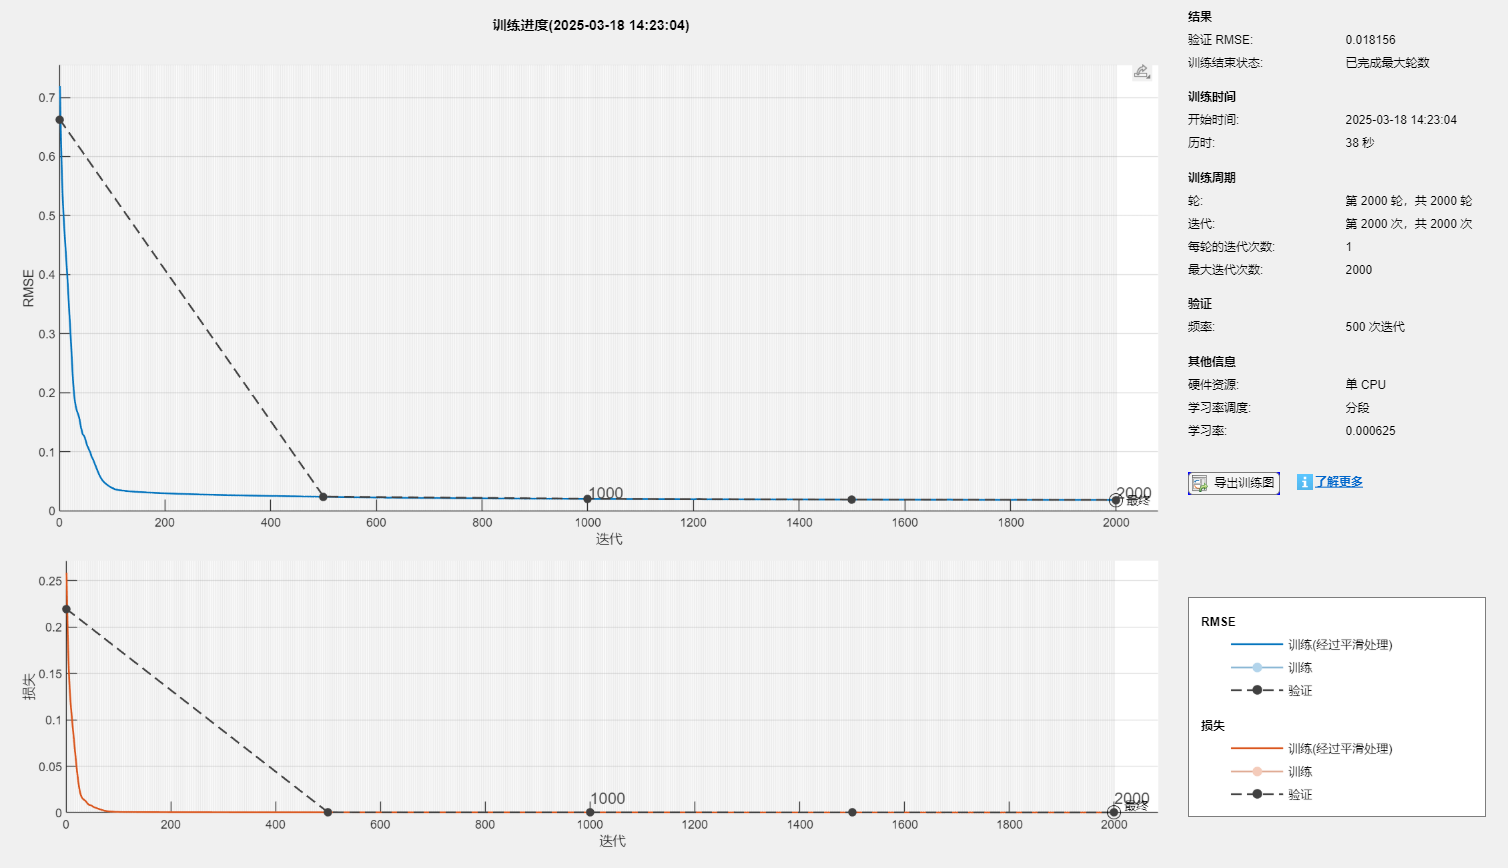

% Design Network and Set Input/Output Matrix 
layers = [
    sequenceInputLayer(6,"Name","sequence")
    fullyConnectedLayer(8,"Name","fc_1")
    reluLayer("Name","relu_1")
    fullyConnectedLayer(8,"Name","fc_2")
    reluLayer("Name","relu_2")
    fullyConnectedLayer(2,"Name","Regression Output")
    regressionLayer("Name","regressionoutput")];

 
M=2; % Memory Depth
X1 = zeros(2*(M + 1), dim-M);
for j = 1:length(y_i) - M
    X1(:, j) = [y_i(j : j + M); y_q(j : j + M)];
end
Y = [x_i(M + 1 : end)'; x_q(M + 1 : end)'];


% Adjust Parameters and Train Models
% More Details in https://ww2.mathworks.cn/help/deeplearning/ref/trainingoptions.html
num = 5000;
XValidation = X1(:, num:end);
YValidation = Y(:, num:end);
maxEpochs = 2000;
miniBatchSize = 512;
options = trainingOptions('adam', ...
    'MaxEpochs', maxEpochs, ...
    'MiniBatchSize', miniBatchSize, ... 
    'InitialLearnRate', 0.005, ...
    'GradientThreshold', 1, ...
    'ValidationData', {XValidation, YValidation}, ...
    'ValidationFrequency', 500, ...
    'Shuffle', 'never', ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'cpu', ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.5, ...
    'LearnRateDropPeriod', 600, ...
    'Verbose', 1, ...
    'VerboseFrequency', 1000);
%   'ValidationPatience',5,...


deep_net = trainNetwork(X1(:, 1:num), Y(:, 1:num), layers, options);


%  Check Modeling Performance and Save Models
Y_pred = predict(deep_net, X1);
a = Y_pred(1, :) + Y_pred(2, :) * 1i;
b = Y(1, :) + Y(2, :) * 1i;
nmse_DPD = NMSE_dB(a, b);
fprintf('DPD的NMSE为 %f dB', nmse_DPD);

DPD的NMSE为 -27.353149 dB


save('Algorithm_A\DeepNN.mat', 'deep_net');